
$$y(x,t)=(c_1+c_2x^2)sin(kx+wt)$$


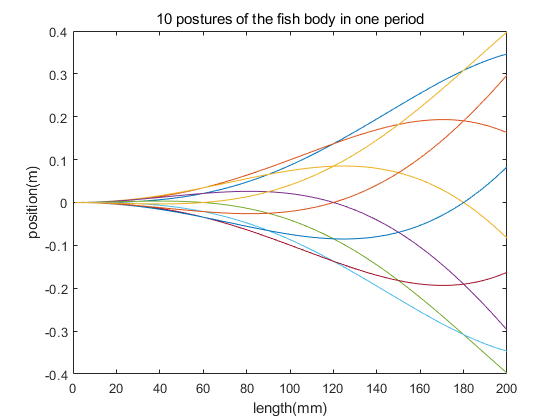

clear;
clc;

lambda = 600; % wave length
L = 200; % fish length
c1 = 0;
c2 = 0.00001;
M = 10; % resolution

x = 1:1:L;
for i = 0:M-1
    %y = sin(x);
    y = (c1+c2*x.*x).*sin(2*pi/lambda*x+2*pi/M*i); % forward motion equation
    plot(x,y);
    hold on;
end
xlabel('length(mm)')
ylabel('position(m)')
title('10 postures of the fish body in one period')
hold off;

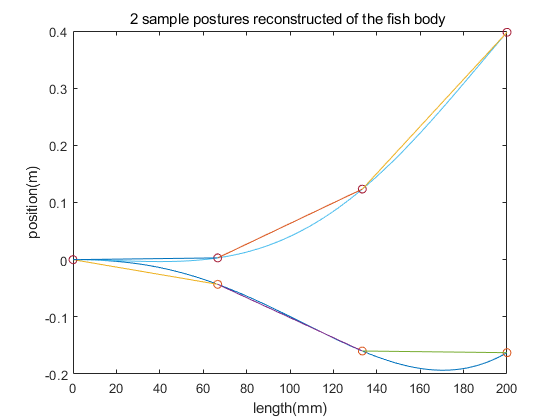

syms f(x);
for i = [6, 9]
    f(x) = (c1+c2*x^2)*sin(2*pi/lambda*x+2*pi/M*i);
    % dy = diff(f(x),x);
    joints = [f(0), f(L/3), f(L/3*2), f(L)];
    
    xx = 1:1:L;
    plot(xx, f(xx));
    hold on;
    plot([0, L/3, L/3*2, L], joints, "o")
    hold on;
    plot([0, L/3], [joints(1), joints(2)])
    hold on;
    plot([L/3, L/3*2], [joints(2), joints(3)])
    hold on;
    plot([L/3*2, L], [joints(3), joints(4)])
    hold on;
end
title('2 sample postures reconstructed of the fish body ')
xlabel('length(mm)')
ylabel('position(m)')
hold off;

syms f1(t) f2(t) f3(t);
T = 2; % period

f1(t) = (c1)*sin(2*pi/T*t);
f2(t) = (c1+c2*(L/3)^2)*sin(2*pi/lambda*(L/3)+2*pi/T*t);
f3(t) = (c1+c2*(L/3*2)^2)*sin(2*pi/lambda*(L/3*2)+2*pi/T*t);
f4(t) = (c1+c2*(L)^2)*sin(2*pi/lambda*(L)+2*pi/T*t);

alpha1(t) = (f2(t)-f1(t))/(L/3)*1000;
alpha2(t) = (f3(t)-f2(t))/(L/3)*1000;
alpha3(t) = (f4(t)-f3(t))/(L/3)*1000;

servo1(t) = atan(alpha1(t))

$$servo1(t) = \mathrm{atan}\left(\frac{2\,\sin\left(\frac{2\,\pi }{9}+\pi \,t\right)}{3}\right)$$

% check the motion waving angle range
% syms x tt
% tt=linspace(0,10,1000);
% x=atan(4.*sin(4.*pi/15+pi.*tt)./5)/pi*180+42;
% plot(tt,x)
servo2(t) = atan(alpha1(t) + alpha2(t))

$$servo2(t) = \mathrm{atan}\left(\frac{8\,\sin\left(\frac{4\,\pi }{9}+\pi \,t\right)}{3}\right)$$

servo3(t) = atan(alpha1(t) + alpha2(t) + alpha3(t))

$$servo3(t) = \mathrm{atan}\left(6\,\sin\left(\frac{2\,\pi }{3}+\pi \,t\right)\right)$$

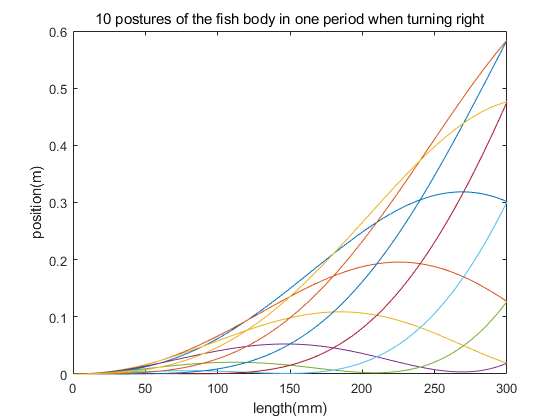

x = 1:1:300;
ka = 0.33; % Amplitude coefficient
ki = 0.5; % Skew coefficient
for i = 0:M-1
    %y = sin(x);
    y = (c1+c2*x.*x).*sin(2*pi/lambda*x+2*pi/M*i)*ka + (1-ka)*ki*(c1+c2*x.*x); % turning right motion equation
    plot(x,y);
    hold on;
end
title('10 postures of the fish body in one period when turning right')
xlabel('length(mm)')
ylabel('position(m)')
hold off;

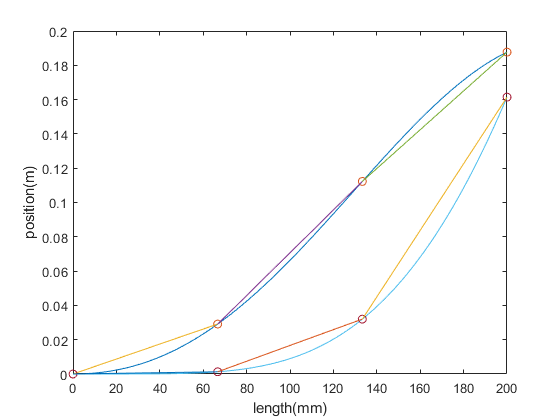

syms f(x);
for i = [1, 7]
    f(x) = (c1+c2*x^2)*sin(2*pi/lambda*x+2*pi/M*i)*ka + (1-ka)*ki*(c1+c2*x*x);
    % dy = diff(f(x),x);
    joints = [f(0), f(L/3), f(L/3*2), f(L)];
    
    xx = 1:1:L;
    plot(xx, f(xx));
    hold on;
    plot([0, L/3, L/3*2, L], joints, "o")
    hold on;
    plot([0, L/3], [joints(1), joints(2)])
    hold on;
    plot([L/3, L/3*2], [joints(2), joints(3)])
    hold on;
    plot([L/3*2, L], [joints(3), joints(4)])
    hold on;
end
xlabel('length(mm)')
ylabel('position(m)')
hold off;

f1(t) = (c1)*sin(2*pi/T*t);
f2(t) = -1.0*((c1+c2*(L/3)^2)*sin(2*pi/lambda*(L/3)+2*pi/T*t)*ka + (1-ka)*ki*(c1+c2*(L/3)^2));
f3(t) = -1.0*((c1+c2*(L/3*2)^2)*sin(2*pi/lambda*(L/3*2)+2*pi/T*t)*ka + (1-ka)*ki*(c1+c2*(L/3*2)^2));
f4(t) = -1.0*((c1+c2*(L)^2)*sin(2*pi/lambda*(L)+2*pi/T*t)*ka + (1-ka)*ki*(c1+c2*(L)^2));

alpha1(t) = (f2(t)-f1(t))/(L/3)*1000;
alpha2(t) = (f3(t)-f2(t))/(L/3)*1000;
alpha3(t) = (f4(t)-f3(t))/(L/3)*1000;

servo1(t) = atan(alpha1(t))

$$servo1(t) = -\mathrm{atan}\left(\frac{11\,\sin\left(\frac{2\,\pi }{9}+\pi \,t\right)}{50}+\frac{67}{300}\right)$$

servo2(t) = atan(alpha1(t) + alpha2(t))

$$servo2(t) = -\mathrm{atan}\left(\frac{22\,\sin\left(\frac{4\,\pi }{9}+\pi \,t\right)}{25}+\frac{67}{75}\right)$$

servo3(t) = atan(alpha1(t) + alpha2(t) + alpha3(t))

$$servo3(t) = -\mathrm{atan}\left(\frac{99\,\sin\left(\frac{2\,\pi }{3}+\pi \,t\right)}{50}+\frac{201}{100}\right)$$

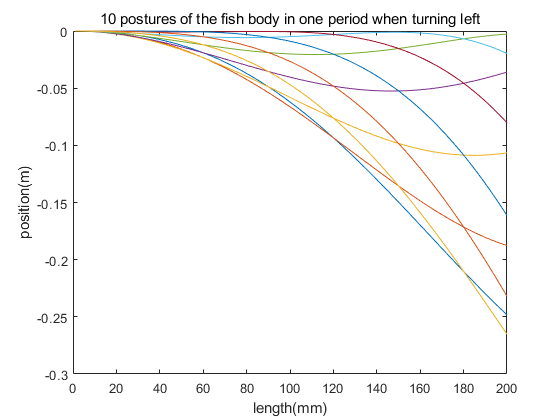

x = 1:1:L;
ka = 0.33; % Amplitude coefficient
ki = 0.5; % Skew coefficient
for i = 0:M-1
    %y = sin(x);
    y = -1 * ((c1+c2*x.*x).*sin(2*pi/lambda*x+2*pi/M*i)*ka + (1-ka)*ki*(c1+c2*x.*x)); % turning left motion equation
    plot(x,y);
    hold on;
end
title('10 postures of the fish body in one period when turning left')
xlabel('length(mm)')
ylabel('position(m)')
hold off;

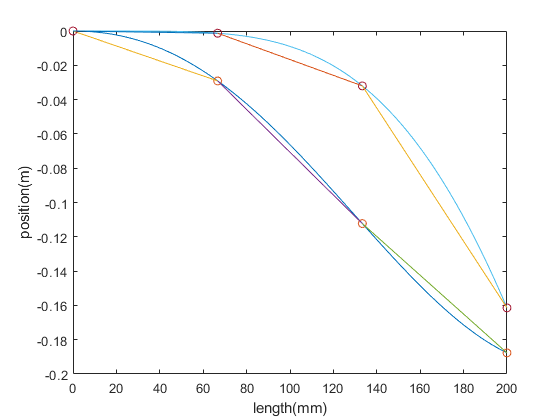

syms f(x);
for i = [1, 7]
    f(x) = (c1+c2*x^2)*sin(2*pi/lambda*x+2*pi/M*i)*ka + (1-ka)*ki*(c1+c2*x*x);
    % dy = diff(f(x),x);
    joints = -[f(0), f(L/3), f(L/3*2), f(L)];
    
    xx = 1:1:L;
    plot(xx, -f(xx));
    hold on;
    plot([0, L/3, L/3*2, L], joints, "o")
    hold on;
    plot([0, L/3], [joints(1), joints(2)])
    hold on;
    plot([L/3, L/3*2], [joints(2), joints(3)])
    hold on;
    plot([L/3*2, L], [joints(3), joints(4)])
    hold on;
end
xlabel('length(mm)')
ylabel('position(m)')
hold off;

syms f1(t) f2(t) f3(t);
T = 2; % period

f1(t) = (c1)*sin(2*pi/T*t);
f2(t) = (c1+c2*(L/3)^2)*sin(2*pi/lambda*(L/3)+2*pi/T*t)*ka + (1-ka)*ki*(c1+c2*(L/3)^2);
f3(t) = (c1+c2*(L/3*2)^2)*sin(2*pi/lambda*(L/3*2)+2*pi/T*t)*ka + (1-ka)*ki*(c1+c2*(L/3*2)^2);
f4(t) = (c1+c2*(L)^2)*sin(2*pi/lambda*(L)+2*pi/T*t)*ka + (1-ka)*ki*(c1+c2*(L)^2);

alpha1(t) = (f2(t)-f1(t))/(L/3)*1000;
alpha2(t) = (f3(t)-f2(t))/(L/3)*1000;
alpha3(t) = (f4(t)-f3(t))/(L/3)*1000;

servo1(t) = atan(alpha1(t))

$$servo1(t) = \mathrm{atan}\left(\frac{11\,\sin\left(\frac{2\,\pi }{9}+\pi \,t\right)}{50}+\frac{67}{300}\right)$$

% syms x tt
% tt=linspace(0,10,1000);
% x=-servo1(tt)/pi*180+42;
% plot(tt,x)
servo2(t) = atan(alpha1(t) + alpha2(t))

$$servo2(t) = \mathrm{atan}\left(\frac{22\,\sin\left(\frac{4\,\pi }{9}+\pi \,t\right)}{25}+\frac{67}{75}\right)$$

servo3(t) = atan(alpha1(t) + alpha2(t) + alpha3(t))

$$servo3(t) = \mathrm{atan}\left(\frac{99\,\sin\left(\frac{2\,\pi }{3}+\pi \,t\right)}{50}+\frac{201}{100}\right)$$